ncdisp("A2017348114000.L2_LAC_SST.nc");

Source:
           C:\_DOCUM\ML\4Lab\20171214 SST Кипр\A2017348114000.L2_LAC_SST.nc
Format:
           netcdf4
Global Attributes:
           title                         = 'HMODISA Level-2 Data'
           product_name                  = 'A2017348114000.L2_LAC_SST.nc'
           processing_version            = '2014.0.1QL'
           equatorCrossingLongitude      = -134.7439
           orbit_number                  = 83083
           history                       = 'l2gen par=/data2/sdpsoper/vdc/vpu5/workbuf/A2017348114000.L1B_LAC.param metafile=A2017348114000.L2_LAC_SST.nc.meta'
           instrument                    = 'MODIS'
           platform                      = 'Aqua'
           Conventions                   = 'CF-1.6 ACDD-1.3'
           license                       = 'http://science.nasa.gov/earth-science/earth-science-data/data-information-policy/'
           naming_authority              = 'gov.nasa.gsfc.sci.oceandata'
           id                            = '2014.0

sst = ncread("A2017348114000.L2_LAC_SST.nc",'geophysical_data/sst');
lat = ncread("A2017348114000.L2_LAC_SST.nc",'navigation_data/latitude');
lot = ncread("A2017348114000.L2_LAC_SST.nc",'navigation_data/longitude');


% imagesc(sst);
% grid on
% colorbar;
% imagesc(lot);
% grid on
% colorbar;
% imagesc(lat);
% grid on
% colorbar;

n=1000

n = 1000

x = linspace(min(min(lat)),max(max(lat)), n);
y = linspace(min(min(lot)),max(max(lot)), n);
Z = zeros(n,n);

for i = 1:size(lat,1)
    for j = 1:size(lat,2)
        [m,indx] = min(abs(x-lat(i,j)));
        [M,indy] = min(abs(y-lot(i,j)));
        Z(indx,indy) = sst(i,j);
    end

end
Z(Z<-10)=0

Z =    NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

f = imagesc(x,y,Z)

f =   Image with properties:

           CData: [1000×1000 double]
    CDataMapping: 'scaled'

  Show all properties


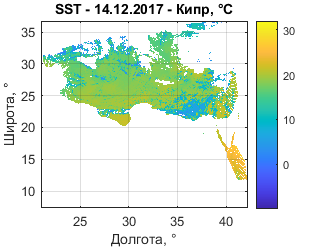

colorbar;
grid on
title('SST - 14.12.2017 - Кипр, °С')
ylabel("Широта, °")
xlabel("Долгота, °")


alpha color
set(gca, 'YDir', 'normal')
saveas(f, 'LABIC4.png')